# Aula 3 - Atividade 1 - Analogia entre vetores e sinais

## Boas Práticas

clear;                %%% limpando as variáveis
close all;            %%% fechando todas as figuras
clc;                  %%% limpando a tela

## Exercício 1:

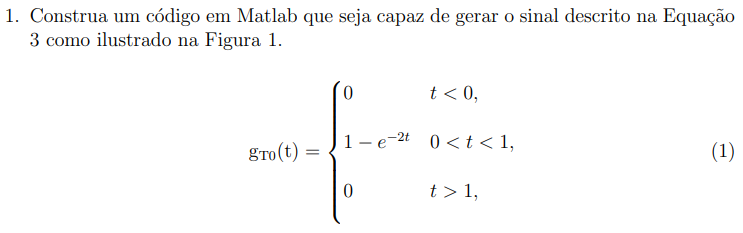

### Ambiente simbólico

syms t;                                        %%% Declaração de variáveis simbólicas
gt0_simbolico(t) = 1 - exp(-2*t)               %%% Determinando o sinal original simbólico

$$gt0\_simbolico(t) = 1-{\mathrm{e}}^{-2\,t}$$

### Visualização gráfica

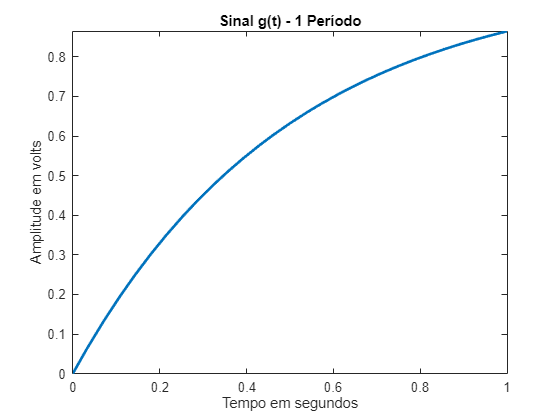

fplot(t,gt0_simbolico(t),[0,1],'LineWidth',2);     %%% Gerando o gráfico            
title('Sinal g(t) - 1 Período');                   %%% Título do gráfico 1
xlabel('Tempo em segundos');                       %%% Eixo x gráfico 1
ylabel('Amplitude em volts');                      %%% Eixo y gráfico 1

## Exercício 2:

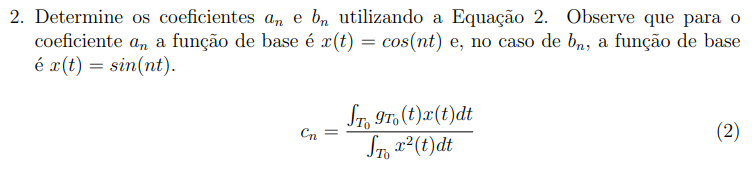

### Ambiente simbólico

syms n t;     %%% Declaração de variáveis simbólicas

### Atribuição de  valores:

%%% Definição dos termos:
%%% t0 --> Valor inicial do intervalo de integração;
%%% t1 --> Valor final do intervalo de integração;
%%% w --> Frequência angular

%%% Atribuindo valores:
t0 = 0;
t1 = 1;
w = 2*pi;

### Determição de an:

#### Determinando an simbolicamente:

num_an = int((1-exp(-2*t))*cos(n*w*t),t,t0,t1);           %%% Numerador de an simbólico              
den_an = int((cos(n*w*t))^2,t,t0,t1);                     %%% Denominador de an simbólico

#### Determinando an numericamente:

num_numerico_an = eval(num_an);                           %%% Cálculo do numerador de an
den_numerico_an = eval(den_an);                           %%% Cálculo do denominador de an

an = num_numerico_an ./ den_numerico_an                   %%% an em forma numerica

$$an = -\frac{\frac{\frac{1218991862308979\,\pi \,n\,\sin\left(2\,\pi \,n\right)}{18014398509481984}-\frac{1218991862308979\,\cos\left(2\,\pi \,n\right)}{18014398509481984}+\frac{5070602400912918119859106409109}{10141204801825835211973625643008}}{\frac{2778046668940015\,n^{2}}{281474976710656}+1}-\frac{\sin\left(2\,\pi \,n\right)}{2\,n\,\pi }}{\frac{\sin\left(4\,\pi \,n\right)}{8\,n\,\pi }+\frac{1}{2}}$$

### Determição de bn:

#### Determinando bn simbolicamente:

%%% Determinando bn simbolicamente
num_bn = int((1-exp(-2*t))*sin(n*w*t),t,t0,t1);           %%% Numerador de bn simbólico
den_bn = int((sin(n*w*t))^2,t,t0,t1);                     %%% Denominador de bn simbólico

#### Determinando bn numericamente:

%%% Determinando bn numericamente:
num_numerico_bn = eval(num_bn);                           %%% Cálculo do numerador de bn             
den_numerico_bn = eval(den_bn);                           %%% Cálculo do denominador de bn

bn = num_numerico_bn ./ den_numerico_bn                   %%% bn em forma numerica

$$bn = -\frac{\frac{\frac{1218991862308979\,\cos\left(\pi \,n\right)\,\sin\left(\pi \,n\right)}{9007199254740992}+\frac{1218991862308979\,n\,\left(\pi \,\left(2\,{\cos\left(\pi \,n\right)}^{2}-1\right)-\frac{1633498112715975}{70368744177664}\right)}{18014398509481984}}{\frac{2778046668940015\,n^{2}}{281474976710656}+1}+\frac{{\sin\left(\pi \,n\right)}^{2}}{n\,\pi }}{\frac{\sin\left(4\,\pi \,n\right)}{8\,n\,\pi }-\frac{1}{2}}$$

## Exercicio 3:

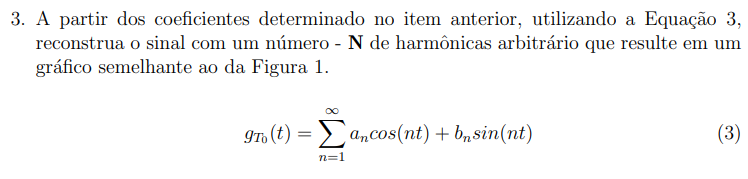

### Variáveis  de ajuste para o plot

%%% Definindo as variáveis para o plot
aux = int(gt0_simbolico(t),t,0,1);                %%% Cálculo de a0 para o ajuste de amplitude do sinal sintetizado, valor medio do sinal do período 
tempo = 0:1e-3:3;                                 %%% Inicio e fim do intervalo de tempo
t1 = 0:1e-3:1;                                    %%% intervalo de tempo 1
t2 = 1:1e-3:2;                                    %%% intervalo de tempo 2
t3 = 2:1e-3:3;                                    %%% intervalo de tempo 3

%%% Declarando o número de harmônicas:
N = 10;                                           %%% Numero de intervalos das harmonicas
n = 1:1:N;                                        %%% Periodo de intervalo das harmonicas

### Variaveis an e bn, de plot, usando o numero de harmônicas:

#### Variavel an de plot:

num_numerico_an_plot = eval(num_an);                                            %%% cálculo do numerador de an, com as harmonicas
den_numerico_an_plot = eval(den_an);                                            %%% cálculo do denominador de an, com as harmonicas

an_plot = num_numerico_an_plot ./ den_numerico_an_plot;                         %%% valores de an de plot

#### Variavel bn de plot:

num_numerico_bn_plot = eval(num_bn);                                            %%% cálculo do numerador de bn, com as harmonicas
den_numerico_bn_plot = eval(den_bn);                                            %%% cálculo do denominador de bn, com as harmonicas

bn_plot = num_numerico_bn_plot ./ den_numerico_bn_plot;                         %%% valores de bn de plot

### Sinal sintetizado

%%% Definição dos termos:
%%% aux --> valor médio do sinal (a0)
%%% w --> frequência angular
%%% tempo --> vetor de instantes do sinal 

%%% O sinal sintetizado é obtido somando as harmônicas
%%% Para cada harmônica k, soma-se:
for k = 1:N
    %%% an_plot(k) * cos(n(k)*w*tempo) --> Componente de cossenos;
    %%% bn_plot(k) * sin(n(k)*w*tempo) --> Componente de senos.
    %%% n(k) --> número da harmônica,
    aux  =  aux + an_plot(k)*cos(n(k)*w*tempo) + bn_plot(k)*sin(n(k)*w*tempo);
end

% Após a soma de todas as harmônicas, a variável 'aux' contém o sinal sintetizado.
gt0_sintetizado = aux;

g1 = 1-exp(-2*(t1));                                                   %%% Calculando os valores de y para o intervalo 1 
g2 = 1-exp(-2*(t2-1));                                                 %%% Calculando os valores de y para o intervalo 2 
g3 = 1-exp(-2*(t3-2));                                                 %%% Calculando os valores de y para o intervalo 3 

### Plot do sinal sintetizado

plot(tempo,gt0_sintetizado,'LineWidth',1,'Color',"k");hold;            %%% Plot do sinal sintetizado

Current plot held


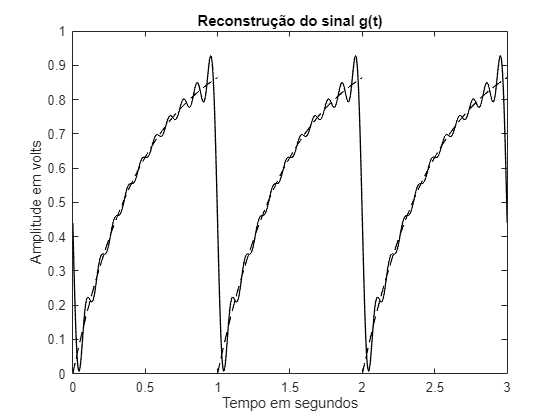

plot(t1,g1,'LineWidth',1,'Color',"k","LineStyle","--");                %%% Plot do intervalo 1
plot(t2,g2,'LineWidth',1,'Color',"k","LineStyle","--");                %%% Plot do intervalo 2
plot(t3,g3,'LineWidth',1,'Color',"k","LineStyle","--");                %%% Plot do intervalo 3

title('Reconstrução do sinal g(t)');                                   %%% Titulo do grafico
xlabel('Tempo em segundos');                                           %%% Nome do eixo x
ylabel('Amplitude em volts');                                          %%% Nome do eixo y

## Exercicio 4:

### Explicação:

Inicialmente, observa-se que o sinal sintetizado difere do sinal original. Embora a forma geral da onda seja semelhante, há discrepâncias notáveis na amplitude e na frequência. Essas diferenças podem ser atribuídas a dois problemas no modelo matemático, os quais, uma vez corrigidos, permitem que o sinal sintetizado se aproxime bastante do sinal original:

#### 1) Ajuste da frequência fundamental (w):

Se analisarmos o período do sinal original, vemos que $T_0=1s$ (enunciado). Dessa forma, temos que a frequência fundamental deve ser: $\omega = \frac{2\pi}{T_0} = \frac{2\pi}{1} = 2\pi \ rad/s$. Esse fator não havia sido considerado na formulação matemática das equações (2) e (3), fazendo com que o número de ciclos no intervalo de 1 a 3 segundos não fosse o esperado. Ao incorporar o fator correto de frequência fundamental, os cálculos passam a refletir o número esperado de ciclos.

#### 2) Correção da amplitude do sinal sintetizado:

A discrepância na amplitude ocorre porque o sinal original possui um valor médio diferente de zero, enquanto a soma de senos e cossenos utilizada na reconstrução tem valor médio nulo. Para compensar essa diferença, é necessário calcular o valor médio do sinal original (ou o coeficiente $a_0$�) e incluí-lo na síntese. Ao somar esse valor médio às contribuições das demais harmônicas, o sinal sintetizado passa a apresentar uma amplitude que se aproxima da do sinal original.

## Exercicio 05:

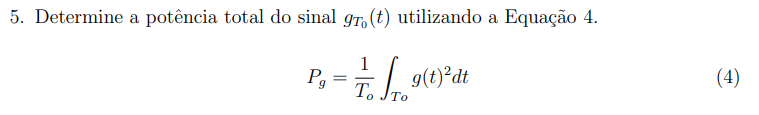

### Cálculo da potência (em watts):

P = int((1 - exp(-2*t))^2, t, 0, 1)     %%% Cálculo da potência

$$P = {\mathrm{e}}^{-2}-\frac{{\mathrm{e}}^{-4}}{4}+\frac{1}{4}$$